## 相位信息重建

Griffin Lim算法

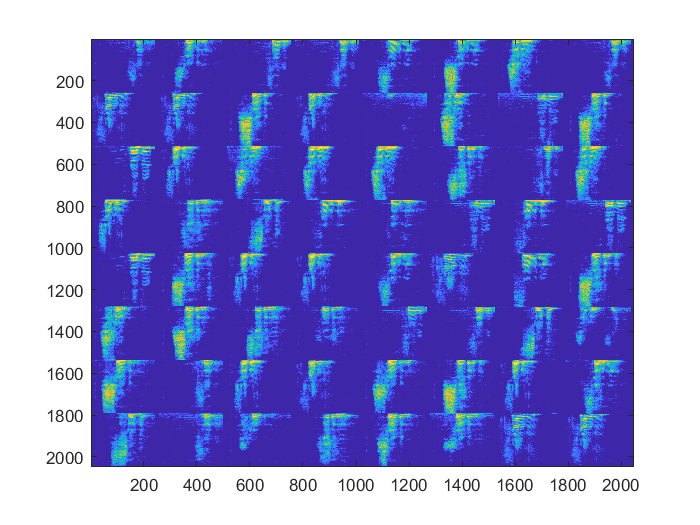

clear;clc;
NFFT=512;
NOVERLAP = NFFT*7/8;
load ('matlab.mat','dlXGeneratedValidation');% 手动保存的
dlXGeneratedValidation = extractdata(gather(dlXGeneratedValidation));
imagesc(imtile(dlXGeneratedValidation))

audio2 = zeros(16000,64);


for i=1:64
    spec = dlXGeneratedValidation(:,:,1,i);
    spec = 10.^(spec*3-3);
    audio2(:,i) = GriffinLim([zeros(1,243);spec(:,1:243)],NFFT,NFFT*7/8);
    
    
end

v=VideoWriter("1.avi");
v.FrameRate =1;v.open();
writeVideo(v,repmat(rescale(dlXGeneratedValidation),1,1,3,1));
v.close();

audiowrite("1.wav",audio2(:),16000);